Parameters

clear;
close all;

landmarks = readtable('lab2_dataset_landmarks.csv');    % [xL, yL]
odometry = readtable('lab2_dataset_odometry.csv');      % [t, deltaSL, deltaSR]
sensors = readtable('lab2_dataset_sensors.csv');        % [t, r1, th1, ..., r6, th6]
trajectory = readtable('lab2_dataset_traj.csv');        % [t, x, y, theta]

% Parameters
l = 0.1;                    % m
sigma_d = 0.5;              % m
sigma_theta = (10*pi)/180;  % rad
sigma_r = 0.5;              % m
sigma_beta = (10*pi)/180;   % rad

P = diag([10, 10, pi^2]);
W = kron(eye(6), diag([sigma_r^2, sigma_beta^2]));  % 12x12
x = [0; 0; 0];
H_w = eye(12);              % 12x12 identity matrix
V = [1, 0; 0 1];

predX = zeros(1000, 1);
predY = zeros(1000, 1);
predTheta = zeros(1000, 1);

Main loop

for i=2:1000
    x(3) = atan2(sin(x(3)), cos(x(3)));

    % Predict
    [x_pred, P_pred] = Prediction(x, odometry.DeltaSL(i), odometry.DeltaSR(i), l, P, V);

    % Correct
    [x_corr, P_corr] = Correction(x_pred, P_pred, sensors, landmarks, W, H_w, i);
    
    x = x_corr;
    P = P_corr;
    
    % Save pose
    predX(i) = x(1);
    predY(i) = x(2);
    predTheta(i) = x(3);
end

Plots

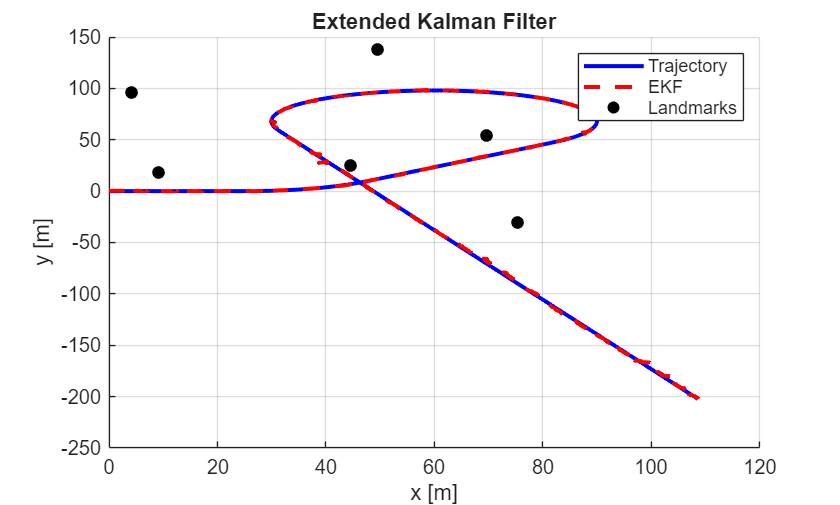

figure; 
hold on; grid on;
plot(trajectory.x, trajectory.y, 'b-',  'LineWidth', 2, 'DisplayName', 'Trajectory');
plot(predX, predY, 'r--', 'LineWidth', 2, 'DisplayName', 'EKF');
scatter(landmarks.xL, landmarks.yL, 40, 'black', 'filled', 'DisplayName', 'Landmarks');
legend; xlabel('x [m]'); ylabel('y [m]'); title('Extended Kalman Filter');

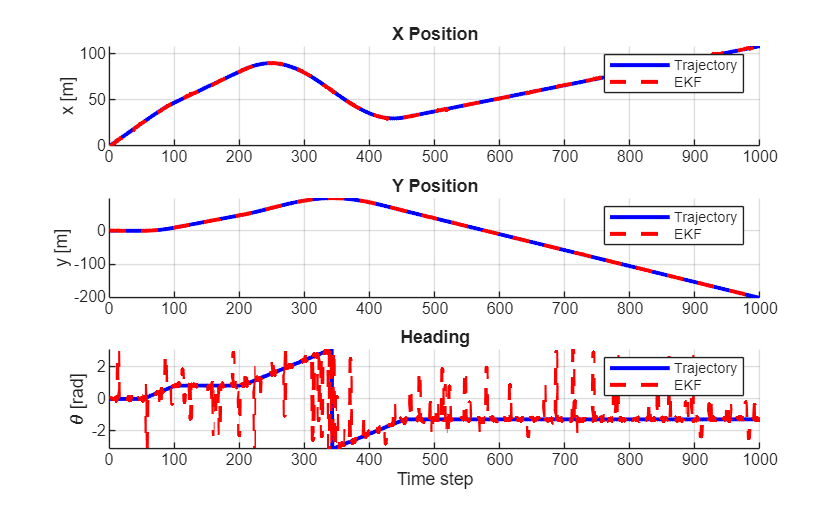


figure;
subplot(3,1,1);
hold on; grid on;
plot(trajectory.x, 'b-', 'LineWidth', 2, 'DisplayName', 'Trajectory');
plot(predX, 'r--', 'LineWidth', 2, 'DisplayName', 'EKF');
legend; ylabel('x [m]'); title('X Position');

subplot(3,1,2);
hold on; grid on;
plot(trajectory.y, 'b-', 'LineWidth', 2, 'DisplayName', 'Trajectory');
plot(predY, 'r--', 'LineWidth', 2, 'DisplayName', 'EKF');
legend; ylabel('y [m]'); title('Y Position');

subplot(3,1,3);
hold on; grid on;
traj_theta_wrapped = atan2(sin(trajectory.theta), cos(trajectory.theta));
plot(traj_theta_wrapped, 'b-', 'LineWidth', 2, 'DisplayName', 'Trajectory');
plot(predTheta, 'r--', 'LineWidth', 2, 'DisplayName', 'EKF');
legend; ylabel('\theta [rad]'); xlabel('Time step'); title('Heading');

Prediction

function [x_pred, P_pred] = Prediction(x, SL, SR, l, P, V)
    % Differential drive motion model 
    dx = [((SL + SR)/2)*cos(x(3));
          ((SL + SR)/2)*sin(x(3));
          (SR - SL)/l];
    
    % Jacobians
    F_x = JacobianFx(SL, SR, x(3));
    F_v = JacobianFv(x(3));
    
    % Prediction equations
    x_pred    = x + dx;
    x_pred(3) = atan2(sin(x_pred(3)), cos(x_pred(3)));
    P_pred = F_x*P*F_x' + F_v*V*F_v';
end

Correction

function [x_corr, P_corr] = Correction(x_pred, P_pred, sensors, landmarks, W, H_w, idx)
    H_x = CalculateHx(x_pred, landmarks);
    v = Innovation(x_pred, sensors, landmarks, idx);
    K = KalmanGain(P_pred, H_x, H_w, W);

    x_corr = x_pred + K*v;
    x_corr(3) = atan2(sin(x_corr(3)), cos(x_corr(3)));
    P_corr = P_pred - K*H_x*P_pred;
end

Jacobians

function F_x = JacobianFx(SL, SR, theta)
    F_x = [1, 0, -((SL + SR) / 2) * sin(theta);
           0, 1,  ((SL + SR) / 2) * cos(theta);
           0, 0,    1];
end


function F_v = JacobianFv(theta)
    F_v = [cos(theta), 0;
           sin(theta), 0;
           0,          1];
end

Hx Matrix Calculations

function H_x = CalculateHx(x_pred, landmarks)
    r = zeros(6, 1);    % 6 landmarks (6x1)
    for i = 1:6 
        r(i, 1) = Distance(x_pred(1), x_pred(2), landmarks.xL(i), landmarks.yL(i));
    end
    
    H_x = zeros(12, 3); % 6 landmarks (12x3)
    for i = 1:6
        dx = landmarks.xL(i) - x_pred(1);
        dy = landmarks.yL(i) - x_pred(2);

        range = 2*i - 1; % row 1, 3, 5,...
        H_x(range, 1) = -dx / r(i);
        H_x(range, 2) = -dy / r(i);
        H_x(range, 3) = 0;

        bearing = 2*i;  % row 2, 4, 6,...
        H_x(bearing, 1) = dy / r(i)^2;
        H_x(bearing, 2) = -dx / r(i)^2;
        H_x(bearing, 3) = -1;
    end
end

Distance

function d = Distance(x, y, xi, yi)
    d = sqrt((yi - y)^2 + (xi - x)^2);
end

Kallman Gain

function K = KalmanGain(P_pred, H_x, H_w, W)
    S = H_x*P_pred*H_x' + H_w*W*H_w';
    K = P_pred*H_x'*inv(S);
end

Innovation

function v = Innovation(x_pred, sensors, landmarks, idx)
    % Sensor measurement
    z = [sensors.r1(idx);  sensors.th1(idx);
         sensors.r2(idx);  sensors.th2(idx);
         sensors.r3(idx);  sensors.th3(idx);
         sensors.r4(idx);  sensors.th4(idx);
         sensors.r5(idx);  sensors.th5(idx);
         sensors.r6(idx);  sensors.th6(idx)];
    
    % Measurment model
    h = zeros(12, 1);
    for i = 1:6
        dx = landmarks.xL(i) - x_pred(1);
        dy = landmarks.yL(i) - x_pred(2);

        h(2*i-1) = sqrt(dx^2 + dy^2);
        h(2*i) = atan2(dy, dx) - x_pred(3);
        %atan2 pi/-pi
    end
      
    % Innovation equation
    v = z - h;

    for i = 1:6
        v(2*i) = atan2(sin(v(2*i)), cos(v(2*i)));
    end
end